Field #2 Central Vertical Fountain and 3 Feeding Fountains

% define constants
% field 1 volumetric flow rate
totalQ = 4000;  % [=] GPM
totalQ = totalQ * 6.309e-5;  % [=] m^3/s
% central outlet - half of total outlet
centralQ = totalQ*0.5;  % [=] m^3/s
% small outlets - one third of remaining volume for each
smallQ = totalQ*0.5/3;  % [=] m^3/s
% pipe diameter
D = 0.0762;  % [=] m
g = 9.8;  % [=] m/s^2

% evaluate position equation for vertical foundtain to find max height,
% as shown in http://physics.bu.edu/~duffy/semester1/c4_maxheight.html
v = centralQ/(pi*(D/2)^2);
maxH = v^2/(2*g);
fprintf("Maximum acheievable height for central fountain: %.1f feet.",maxH*3.28)

Maximum acheievable height for central fountain: 128.1 feet.

% angle needed for the outer 3 fountains to shoot into central one from 20
% ft away
launchAngle = 68;  % [=] degrees
v = smallQ/(pi*(D/2)^2);
d = v^2 * sin ( 2 * pi * launchAngle / 180) / g;
fprintf("Distance traveled with a launch angle of %.0f degrees: %0.1f feet",launchAngle,d*3.28)

Distance traveled with a launch angle of 68 degrees: 19.8 feet

Hill #2 Cascading Waterfall Stairs - outlet at the top of Hill #2 and collects via a small stream into the central fountain in field #2

% find the length of the side of hill 2
L = sqrt(50^2 + 100^2);  % [=] ft
L = L / 3.28;  % [=] m
% set the width of the stair fountain feature to be only part of the width
% of the hill
W = 40;  % [=] ft
W = W / 3.28;  % [=] m
% for aesthetic reasons, we want to maintain one inch of water over this
% area
% ensure that the flow rate from the simulation can satisfy this
hillFlow = 2900;  % [=] GPM
hillFlow = hillFlow * 6.309e-5;  % [=] m^3/s
depth = hillFlow / (L * W/60);
fprintf("Depth of water on Hill 2 Waterfall Stairs: %.2f inches.",depth*39.37)

Depth of water on Hill 2 Waterfall Stairs: 1.04 inches.

Field #1 Feature - 3 Rotating Fountains attached to a central pivot, conceptually similar to:

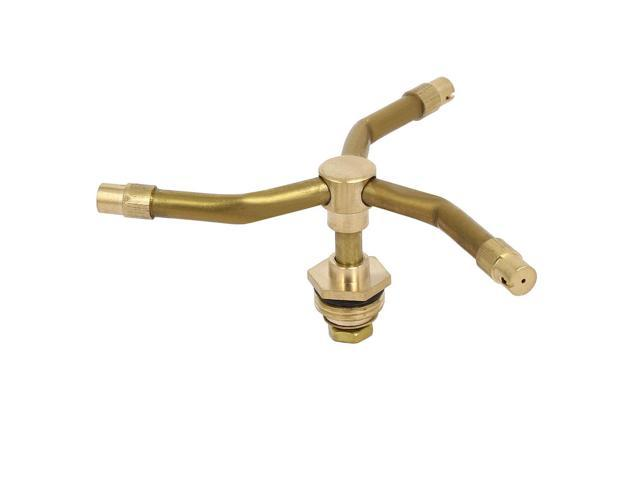

% inlet volumetric flow rate and Q for each outlet
totalQ = 300;  % [=] GPM
totalQ = totalQ * 6.309e-5;  % [=] m^3/s
outletQ = totalQ / 3;  % [=] m^3/s
% make the diameter at each outlet smaller to increase velocity
D = D/3;  % [=] m
% repeat above calculation to ensure the water will not launch out of the
% fountain
launchAngle = 85;  % [=] degrees
v = outletQ/(pi*(D/2)^2);
d = v^2 * sin ( 2 * pi * launchAngle / 180) / g;
% calculate how high the water will go for aesthetic puposes
maxH = v^2/(2*g);
fprintf("Distance traveled with a launch angle of %.0f degrees: %0.1f feet. Maximum height: %.2f feet",launchAngle,d*3.28,maxH*3.28)

Distance traveled with a launch angle of 85 degrees: 9.0 feet. Maximum height: 25.94 feet

% ensure that the rotaiton is slow enough to not cause any danger
horzVel = v*cos(launchAngle*pi/180);
fprintf("With a volumetric flow rate of %.0f gallons per minute, the velocity of the fountain apparatus will be %.2f feet per second.",totalQ/6.309e-5,horzVel*3.28*3)

With a volumetric flow rate of 300 gallons per minute, the velocity of the fountain apparatus will be 10.68 feet per second.